# **Dusk power spectra**

clear
load('trimmed_resultsNO20.mat');
load("succession_suncycle.mat");

dusk_d1 = d1_sSET:0.25:d1_dusk;
dusk_d2 = d2_sSET:0.25:d2_dusk;
dusk_d3 = d3_sSET:0.25:d3_dusk;
dusk_d4 = d4_sSET:0.25:d4_dusk;
dusk_d5 = d5_sSET:0.25:d5_dusk;
dusk_d6 = d6_sSET:0.25:d6_dusk;

% Set band limits and sample number
low_only =  find(freqlist>=150 & freqlist<=2000);

Plot with mean and quantiles

%%% INDRA
I1_dusk = NaN(length(freqlist),length(dusk_d1),size(Indra_1_poavg,2)/96);
for i = 1:length(dusk_d1)
    a = find(hrmn_edtI1 == dusk_d1(i));
    I1_dusk(:,i,:) = Indra_1_poavg(:,a);
end
I1_dusk = reshape(I1_dusk, [length(freqlist),(size(I1_dusk,2)*size(I1_dusk,3))]);

% I2
I2_dusk = NaN(length(freqlist),length(dusk_d2),size(Indra_2_poavg,2)/96);
for i = 1:length(dusk_d2)
    a = find(hrmn_edtI2 == dusk_d2(i));
    I2_dusk(:,i,:) = Indra_2_poavg(:,a);
end
I2_dusk = reshape(I2_dusk, [length(freqlist),(size(I2_dusk,2)*size(I2_dusk,3))]);

% I3
I3_dusk = NaN(length(freqlist),length(dusk_d3),size(Indra_3_poavg,2)/96);
for i = 1:length(dusk_d3)
    a = find(hrmn_edtI3 == dusk_d3(i));
    I3_dusk(:,i,:) = Indra_3_poavg(:,a);
end
I3_dusk = reshape(I3_dusk, [length(freqlist),(size(I3_dusk,2)*size(I3_dusk,3))]);

% I4
I4_dusk = NaN(length(freqlist),length(dusk_d4),size(Indra_4_poavg,2)/96);
for i = 1:length(dusk_d4)
    a = find(hrmn_edtI4 == dusk_d4(i));
    I4_dusk(:,i,:) = Indra_4_poavg(:,a);
end
I4_dusk = reshape(I4_dusk, [length(freqlist),(size(I4_dusk,2)*size(I4_dusk,3))]);

% I5
hrmn_edtI5 = round2(hrmn_edtI5, 0.25);
hrmn_edtI5(find(hrmn_edtI5 == 24)) = 0;
%I5_dusk = NaN(length(freqlist),length(dusk_d5),size(Indra_5_poavg,2)/96);
for i = 1:length(dusk_d5)
    a = find(hrmn_edtI5 == dusk_d5(i));
    I5_dusk(:,i,:) = Indra_5_poavg(:,a);
end
I5_dusk = reshape(I5_dusk, [length(freqlist),(size(I5_dusk,2)*size(I5_dusk,3))]);

% I6
I6_dusk = NaN(length(freqlist),length(dusk_d6),size(Indra_6_poavg,2)/96);
for i = 1:length(dusk_d6)
    a = find(hrmn_edtI6 == dusk_d6(i));
    I6_dusk(:,i,:) = Indra_6_poavg(:,a);
end
I6_dusk = reshape(I6_dusk, [length(freqlist),(size(I6_dusk,2)*size(I6_dusk,3))]);
I6_dusk = I6_dusk(:,1:26); % remove files with unknown harmonics
I6_dusk(:,[24 25]) = []; % remove general noisy files


%%% JJ Tug
% J1
%J1_dusk = NaN(length(freqlist),length(dusk_d2),size(JJTug_1_poavg,2)/96);
for i = 1:length(dusk_d1)
    a = find(hrmn_edtJ1(1:672) == dusk_d1(i));
    J1_dusk(:,i,:) = JJTug_1_poavg(:,a);
end
J1_dusk = reshape(J1_dusk, [length(freqlist),(size(J1_dusk,2)*size(J1_dusk,3))]);

% J2
hrmn_edtJ2 = round2(hrmn_edtJ2, 0.25);
%J2_dusk = NaN(length(freqlist),length(dusk_d2),size(JJTug_2_poavg,2)/96);
for i = 1:length(dusk_d2)
    a = find(hrmn_edtJ2(1:576) == dusk_d2(i));
    J2_dusk(:,i,:) = JJTug_2_poavg(:,a);
end
J2_dusk = reshape(J2_dusk, [length(freqlist),(size(J2_dusk,2)*size(J2_dusk,3))]);

% I3
%J3_dusk = NaN(length(freqlist),length(dusk_d3),size(JJTug_3_poavg,2)/96);
for i = 1:length(dusk_d3)
    a = find(hrmn_edtJ3 == dusk_d3(i));
    J3_dusk(:,i,:) = JJTug_3_poavg(:,a);
end
J3_dusk = reshape(J3_dusk, [length(freqlist),(size(J3_dusk,2)*size(J3_dusk,3))]);

% J4
%J4_dusk = NaN(length(freqlist),length(dusk_d4),size(JJTug_4_poavg,2)/96);
for i = 1:length(dusk_d4)
    a = find(hrmn_edtJ4(1:480) == dusk_d4(i));
    J4_dusk(:,i,:) = JJTug_4_poavg(:,a);
end
J4_dusk = reshape(J4_dusk, [length(freqlist),(size(J4_dusk,2)*size(J4_dusk,3))]);

% J5
%J5_dusk = NaN(length(freqlist),length(dusk_d5),size(JJTug_5_poavg,2)/96);
for i = 1:length(dusk_d5)
    a = find(hrmn_edtJ5 == dusk_d5(i));
    J5_dusk(:,i,:) = JJTug_5_poavg(:,a);
end
J5_dusk = reshape(J5_dusk, [length(freqlist),(size(J5_dusk,2)*size(J5_dusk,3))]);

% J6
%J6_dusk = NaN(length(freqlist),length(dusk_d6),size(JJTug_6_poavg,2)/96);
for i = 1:length(dusk_d6)
    a = find(hrmn_edtJ6(1:576) == dusk_d6(i));
    J6_dusk(:,i,:) = JJTug_6_poavg(:,a);
end
J6_dusk = reshape(J6_dusk, [length(freqlist),(size(J6_dusk,2)*size(J6_dusk,3))]);
J6_dusk = J6_dusk(:,1:28); % remove files with unknown harmonics
J6_dusk(:,[22 25 27]) = []; % remove general noisy files


dusk_all = {I1_dusk I2_dusk I3_dusk I4_dusk I5_dusk I6_dusk J1_dusk J2_dusk J3_dusk J4_dusk J5_dusk J6_dusk};


Calculate median, mean, and quantiles for low frequency band


for j = 1:length(dusk_all)
    current = dusk_all{j};
    mean_spec(:,j) = mean(current(low_only,:),2);
    median_spec(:,j) = median(current(low_only,:),2);
    quantile95(:,j) = quantile(current(low_only, :),.95,2);
    quantile5(:,j) = quantile(current(low_only, :),.05,2);
end


Plotting

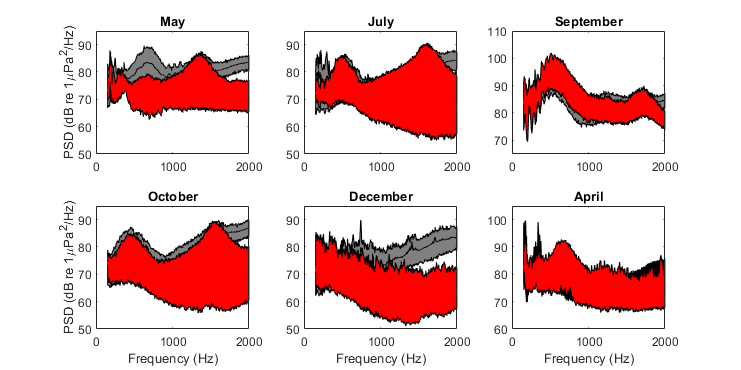

 
figure;
subplot(2,3,1); set(gcf,'units','centimeters','position',[0,0,19.6,9.8]);
%shsemilogx(freqlist(low_only),10*log10(quantile5(:,1)),10*log10(quantile95(:,1)),[0.5 0.5 0.5]);hold on;
ciplot(10*log10(quantile5(:,1)),10*log10(quantile95(:,1)),freqlist(low_only),[0.5 0.5 0.5]);hold on;
plot(freqlist(low_only),10*log10(mean_spec(:,1)),'k'); hold on;
ciplot(10*log10(quantile5(:,7)),10*log10(quantile95(:,7)),freqlist(low_only),'r');hold on;
plot(freqlist(low_only),10*log10(median_spec(:,7)),'r'); hold on; ylim([50 95]);
title('May',"FontSize",14);
%xlabel('Frequency(Hz)');
ylabel('PSD (dB re 1\muPa^2/Hz)',"FontSize",14);

subplot(2,3,2);
ciplot(10*log10(quantile5(:,2)),10*log10(quantile95(:,2)),freqlist(low_only),[0.5 0.5 0.5]);hold on;
plot(freqlist(low_only),10*log10(mean_spec(:,2)),'k'); hold on;
ciplot(10*log10(quantile5(:,8)),10*log10(quantile95(:,8)),freqlist(low_only),'r');hold on;
plot(freqlist(low_only),10*log10(median_spec(:,8)),'r'); hold on;ylim([50 95]);
title('July',"FontSize",14);
%xlabel('Frequency(Hz)');
%ylabel('PSD');

subplot(2,3,3);
ciplot(10*log10(quantile5(:,3)),10*log10(quantile95(:,3)),freqlist(low_only),[0.5 0.5 0.5]);hold on;
plot(freqlist(low_only),10*log10(mean_spec(:,3)),'k'); hold on;
ciplot(10*log10(quantile5(:,9)),10*log10(quantile95(:,9)),freqlist(low_only),'r');hold on;
plot(freqlist(low_only),10*log10(median_spec(:,9)),'r'); hold on;ylim([65 110]);
title('September',"FontSize",14);
%xlabel('Frequency(Hz)');

subplot(2,3,4);
ciplot(10*log10(quantile5(:,4)),10*log10(quantile95(:,4)),freqlist(low_only),[0.5 0.5 0.5]);hold on;
plot(freqlist(low_only),10*log10(mean_spec(:,4)),'k'); hold on;
ciplot(10*log10(quantile5(:,10)),10*log10(quantile95(:,10)),freqlist(low_only),'r');hold on;
plot(freqlist(low_only),10*log10(median_spec(:,10)),'r'); hold on;ylim([50 95]);
title('October',"FontSize",14);
xlabel('Frequency (Hz)',"FontSize",14);
ylabel('PSD (dB re 1\muPa^2/Hz)',"FontSize",14);

subplot(2,3,5);
ciplot(10*log10(quantile5(:,5)),10*log10(quantile95(:,5)),freqlist(low_only),[0.5 0.5 0.5]);hold on;
plot(freqlist(low_only),10*log10(mean_spec(:,5)),'k'); hold on;
ciplot(10*log10(quantile5(:,11)),10*log10(quantile95(:,11)),freqlist(low_only),'r');hold on;
plot(freqlist(low_only),10*log10(median_spec(:,11)),'r'); hold on;ylim([50 95]);
title('December',"FontSize",14);
xlabel('Frequency (Hz)',"FontSize",14);
%ylabel('PSD');


subplot(2,3,6);
ciplot(10*log10(quantile5(:,6)),10*log10(quantile95(:,6)),freqlist(low_only),'k');hold on;
semilogx(freqlist(low_only),10*log10(mean_spec(:,6)),'k'); hold on;
ciplot(10*log10(quantile5(:,12)),10*log10(quantile95(:,12)),freqlist(low_only),'r');hold on;
semilogx(freqlist(low_only),10*log10(median_spec(:,12)),'r'); hold on;ylim([60 105]);
title('April',"FontSize",14);
xlabel('Frequency (Hz)',"FontSize",14);